PROYECTO 3. S&S SEÑALES Y SISTEMAS. PARTE 1.

Variables Iniciales Generales

n_bits=16;
fs=16000;
n_channels=1;
Td=2;--

Punto 1) Grabación y almacenamiento de audios 

Letra I

%Ingrese opcion para grabar los audios:
%AUDIO 1
avisoI1= input('Presione la letra "s" para iniciar la primera grabación: ','s' );
if avisoI1=='s' %Grabar voz
   LetraI1=audiorecorder(fs,n_bits,n_channels,-1); 
   disp('inicia grabacion 1 (2 segundos)');
   recordblocking(LetraI1,Td);
   disp('fin de grabacion 1');
   LetraI_t1=getaudiodata(LetraI1);
   audiowrite('carpeta I/Letra I_1.wav',LetraI_t1, fs);
end

inicia grabacion 1 (2 segundos)


fin de grabacion 1



%AUDIO 2
avisoI2= input('Presione la letra "s" para iniciar la segunda grabación: ','s' );
if avisoI2=='s' %Grabar voz
    LetraI2=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 2 (2 segundos)');
    recordblocking(LetraI2,Td);
    disp('Fin de grabacion 2');
    LetraI_t2=getaudiodata(LetraI2);
    audiowrite('carpeta I/Letra I_2.wav',LetraI_t2, fs);
end

inicia grabacion 2 (2 segundos)


Fin de grabacion 2



%AUDIO 3
avisoI3= input('Presione la letra "s" para iniciar la tercera grabación: ','s' );
if avisoI3=='s' %Grabar voz
    LetraI3=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 3 (2 segundos)')
    recordblocking(LetraI3,Td);
    disp('Fin de grabacion 3');
    LetraI_t3=getaudiodata(LetraI3);
    audiowrite('carpeta I/Letra I_3.wav',LetraI_t3, fs);
end

inicia grabacion 3 (2 segundos)


Fin de grabacion 3


Punto 2) Carga, información, visualización de gráficas y reproducción de audios

    %Cargar audios
    audioread('carpeta I/Letra I_1.wav');
    audioread('carpeta I/Letra I_2.wav');
    audioread('carpeta I/Letra I_3.wav');
    
    %Informacion general de las señales de audio
    fs=16000;
    Ts=1/fs;
    N=length(LetraA_t2);
    Td=N*Ts;
    t=[0:Ts:Td-Ts];

    %la misma duracion, frecuencia de muestreo, bits y canales son usados en los 9 audios.
    fprintf('----------------Información General-----------------');

----------------Información General-----------------

    fprintf('La duracion de las señales es de: %6.1f', Td);

La duracion de las señales es de:    2.0

    fprintf('La frecuencia de muestreo de las señales es de: %6.1f', fs);

La frecuencia de muestreo de las señales es de: 16000.0

    fprintf('El número de muestras N de las señales es de: %6.1f', N);

El número de muestras N de las señales es de: 32000.0

    fprintf('El número de bits por muestra de las señales es de: %6.1f', n_bits);

El número de bits por muestra de las señales es de:   16.0

    fprintf('El número de canales de las señales es: %6.1f', n_channels);

El número de canales de las señales es:    1.0


    %Gráficas en tiempo:
    fprintf('-----------Gráficas en tiempo-----------------------');

-----------Gráficas en tiempo-----------------------

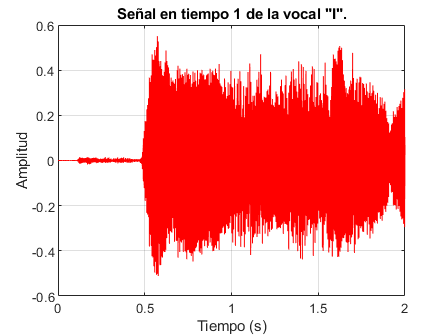

        %I1
    plot(t ,LetraI_t1, 'r-'), grid on
    title(['Señal en tiempo 1 de la vocal "I".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

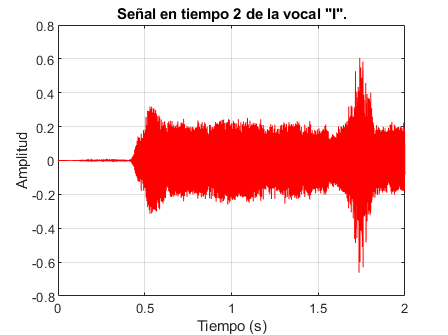

        %I2
    plot(t ,LetraI_t2, 'r-'), grid on
    title(['Señal en tiempo 2 de la vocal "I".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

        %I3
    plot(t ,LetraI_t3, 'r-'), grid on
    title(['Señal en tiempo 3 de la vocal "I".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;
    
    %Reproducción de audios
    fprintf('-------------Reproducción de audios------------------');

-------------Reproducción de audios------------------

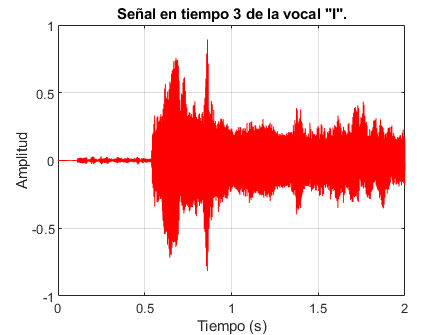

    pause(4);

    disp('Reproduciendo audio I1');

Reproduciendo audio I1


    play(LetraI1);
    pause(4);
    disp('Reproduciendo audio I2');

Reproduciendo audio I2


    play(LetraI2);
    pause(4);
    disp('Reproduciendo audio I3');

Reproduciendo audio I3


    play(LetraI3);

Punto 3) Energía, Transformada de Fourier 

    % Energía total señal 
    fprintf('-----------Energía de las señales--------------------');

-----------Energía de las señales--------------------

    abs_EI1=(abs(LetraI_t1)).^2;
    abs_EI2=(abs(LetraI_t2)).^2;
    abs_EI3=(abs(LetraI_t3)).^2;

    Energy_I1=sum(abs_EI1,"all");
    Energy_I2=sum(abs_EI2,"all");
    Energy_I3=sum(abs_EI3,"all");
    fprintf('La energía en la señal I-1 es: %6.1f', Energy_I1);

La energía en la señal I-1 es:  365.5

    fprintf('La energía en la señal I-2 es: %6.1f', Energy_I2);

La energía en la señal I-2 es:  209.8

    fprintf('La energía en la señal I-3 es: %6.1f', Energy_I3);

La energía en la señal I-3 es:  443.2


    %FFT-Gráficas
    deltaf=1/Td;
    f=[0:deltaf:fs-deltaf];
    fprintf('-----------Gráficas en frecuencia-------------------');

-----------Gráficas en frecuencia-------------------

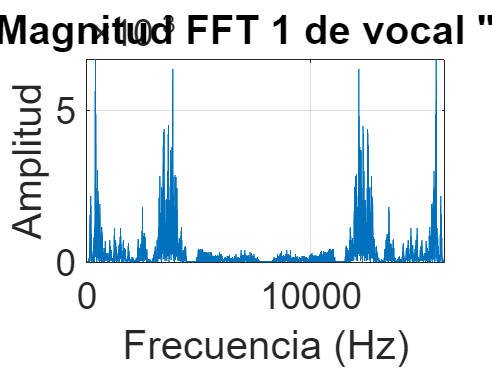

        %I1
    LetraI_f1=fft(LetraI_t1)/N;
    %Frec_I1db = 20*log(abs(LetraI_f1));
    plot(f, abs(LetraI_f1)), grid on
    title(['Magnitud FFT 1 de vocal "I".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;

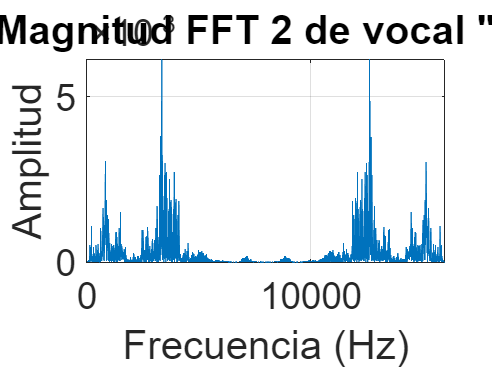


        %A2
    LetraI_f2=fft(LetraI_t2)/N;
    %Frec_I2db = 20*log(abs(LetraI_f2));
    plot (f, abs(LetraI_f2)), grid on
    title(['Magnitud FFT 2 de vocal "I".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;

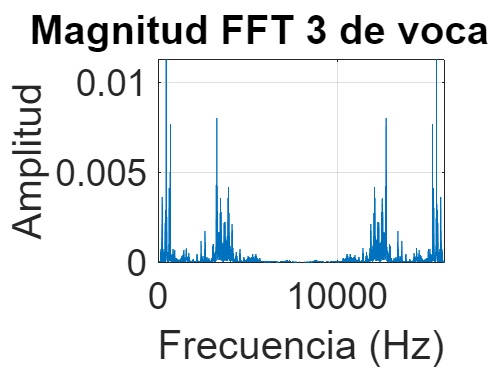


       %A3
    LetraI_f3=fft(LetraI_t3)/N;
    %Frec_I3db = 20*log(abs(LetraI_f3));
    plot (f, abs(LetraI_f3)), grid on
    title(['Magnitud FFT 3 de vocal "I".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;


    % Porcentaje de energía de 200Hz - 1200Hz
    fprintf('--------Energía entre 200-1200 Hz-----------------');

--------Energía entre 200-1200 Hz-----------------

        %I1
    rangoI1=LetraI_f1(400:2400);
    MagI1=(abs(rangoI1)).^2;
    SumI1=sum(MagI1,"all")*N;
    fprintf('La energía (J) en la señal I-1 de 200 Hz a 1200 Hz es: %6.1f', SumI1);

La energía (J) en la señal I-1 de 200 Hz a 1200 Hz es:   48.4

    Porc_EI1=(SumA1/Energy_I1)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EI1); 

Su porcentaje de energía es:    1.5

        %I2
    rangoI2=LetraI_f2(400:2400);
    MagI2=(abs(rangoI2)).^2;
    SumI2=sum(MagI2,"all")*N;
    fprintf('\nLa energía (J) en la señal I-2 de 200 Hz a 1200 Hz es: %6.1f', SumI2);


La energía (J) en la señal I-2 de 200 Hz a 1200 Hz es:   22.6

    Porc_EI2=(SumI2/Energy_I2)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EI2);   

Su porcentaje de energía es:   10.8

        %I3
    rangoI3=LetraI_f3(400:2400);
    MagI3=(abs(rangoI3)).^2;
    SumI3=sum(MagI3,"all")*N;
    fprintf('\nLa energía en la señal I-3 de 200 Hz a 1200 Hz es: %6.1f', SumI3);


La energía en la señal I-3 de 200 Hz a 1200 Hz es:  118.8

    Porc_EI3=(SumI3/Energy_I3)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EI3);   

Su porcentaje de energía es:   26.8